%Start by deciding the distribution of magnetization

[nnDataX,nnDataY] = meshgrid(0:2e-8:400e-8,0:2e-8:400e-8);

Moment = padarray(fspecial('disk',50),[50 50]);
%Moment = fspecial('disk',100);
Moment = Moment.*4.73816e-8./(max(max(Moment)));

Moment = zeros(100, 100)

Moment =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

for i = 1:100 
    for j = 1:100
        if i > 10 && i < 90 && j > 10 && j < 90
            Moment(i,j) = (i-10)/80;
        else
            Moment(i,j) = 0;
        end
    end
end

%Z = zeros(201,201);

%Z(25:175,25:175) = Moment;

M.X = nnDataX;
M.Y = nnDataY;
M.z = Moment;

M.x = [M.X(1,1) M.X(end,end)];
M.y = [M.Y(end,end) M.Y(1,1)];

%Convert magnetization to a magnetic field for a given height above the
%sample
B = ConvertMomenttoB(M, 140e-9,0);


pcolor(Moment)
caxis([-1,1])
h = colorbar

h =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-1 1]
    FontSize: 9
    Position: [0.8500 0.1095 0.0286 0.8155]
       Units: 'normalized'

  Show all properties


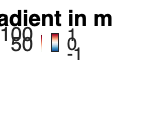

colormap(customcolormap_preset('red-white-blue'))
title('Gradient in m')
xlabel('X (A.U.)')
ylabel('Y (A.U.)')
shading flat

pcolor(B.z)
colormap(customcolormap_preset('red-white-blue'))
hold on
caxis([-1,1])
h = colorbar

h =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-1 1]
    FontSize: 9
    Position: [0.8500 0.1095 0.0286 0.8155]
       Units: 'normalized'

  Show all properties


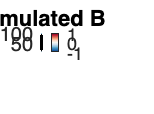

title('Simulated B')
xlabel('X (A.U.)')
ylabel('Y (A.U.)')
plot([10 10],[10 90], 'LineStyle','-.', 'LineWidth',1, 'Color','black')
plot([90 90],[10 90], 'LineStyle','-.', 'LineWidth',1, 'Color','black')
plot([10 90],[10 10], 'LineStyle','-.', 'LineWidth',1, 'Color','black')
plot([10 90],[90 90], 'LineStyle','-.', 'LineWidth',1, 'Color','black')
shading flat
hold off

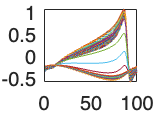

function [Bfield] = ConvertMomenttoB(A, d, Pad_or_Not)

%gimmeB Calculates magnetic field above a uniformly magnetized 2D heterostructure.   
%   This function calculates the magnetic field in the region above a 2D
%   heterostructure.  It discretizes the magnetization density and then
%   computes the field contribution from each magnetic moment.  Variable
%   definitions: moments is the matrix of magnetic moment locations, it is
%   a Boolean matrix; inter_pixel_distance is the distance between pixels,
%   right now I haven't accounted for a non-unitary aspect ratio;
%   mag_density is the magnetic moment per unit area of the material, which
%   is something you'll have to calculate.  In the case of an exfoliated
%   magnetic insulator it will be fairly easy, just magnetic moments of the
%   atoms divided by the unit cell; d is the height of the tip above the
%   magnetic material (not the surface if there's a BN in the way)

if ~exist('Pad_or_Not') | Pad_or_Not == 0
    moments = A.z;
    [rows , cols]= size(moments); 
    kx = zeros(rows, cols);
    ky = zeros(rows, cols);
    dx = (A.x(2) - A.x(1)) / (cols - 1);
    dy = (A.y(1) - A.y(2)) / (rows - 1);
    dkx = 2 * pi / dx;
    dky = 2 * pi / dy;
    %moments = moments .* mag_density;
    fftmoments = fftshift(fft2(moments)) / (rows * cols);
    fftBfield = zeros(rows, cols);
    miu = 4 * pi * 10 ^ (-7);
    % magnetization_per_moment = mag_density / (inter_pixel_distance ^ 2);

    %For even number of columns
    if mod(cols,2) == 0
        for m = 1:rows
            kx(m, :) = (-cols/2:cols/2-1) * dkx / cols;
        end
    else %for odd number of columns
        for m = 1:rows
            kx(m, :) = (-(cols-1)/2:(cols-1)/2) * dkx / cols;
        end
    end

    %For even number of rows
    if mod(rows, 2) == 0
        for n = 1:cols
            ky(:, n) = (-rows/2:rows/2-1) * dky / rows;
        end
    else %for odd number of rows
        for n = 1:cols
            ky(:, n) = (-(rows-1)/2:(rows-1)/2) * dky / rows;
        end 
    end


    for i = 1 : rows
        for j = 1 : cols
            k = sqrt(kx(i, j) ^ 2 + ky(i, j) ^ 2);
            fftBfield(i, j) =  miu * k * exp(-k * d) * fftmoments(i, j) / 2;
        end
    end

    Bfield.z = real(ifft2(ifftshift(fftBfield)) * (rows * cols));
    Bfield.x = A.x;
    Bfield.y = A.y;
    Bfield.X = A.X;
    Bfield.Y = A.Y;
elseif Pad_or_Not == 1
    moments = A.z;
    
    [p, q] = size(moments);
    [paddedmoments, original_coords] = GaussianPadding(moments, 1);
    [rows, cols] = size(paddedmoments);
    
    kx = zeros(rows, cols);
    ky = zeros(rows, cols);
    dx = (A.x(2) - A.x(1)) / (q - 1);
    dy = (A.y(1) - A.y(2)) / (p - 1);
    dkx = 2 * pi / dx;
    dky = 2 * pi / dy;
    %moments = moments .* mag_density;
    fftmoments = fftshift(fft2(paddedmoments)) / (rows * cols);
    fftBfield = zeros(rows, cols);
    miu = 4 * pi * 10 ^ (-7);
    % magnetization_per_moment = mag_density / (inter_pixel_distance ^ 2);

    %For even number of columns
    if mod(cols,2) == 0
        for m = 1:rows
            kx(m, :) = (-cols/2:cols/2-1) * dkx / cols;
        end
    else %for odd number of columns
        for m = 1:rows
            kx(m, :) = (-(cols-1)/2:(cols-1)/2) * dkx / cols;
        end
    end

    %For even number of rows
    if mod(rows, 2) == 0
        for n = 1:cols
            ky(:, n) = (-rows/2:rows/2-1) * dky / rows;
        end
    else %for odd number of rows
        for n = 1:cols
            ky(:, n) = (-(rows-1)/2:(rows-1)/2) * dky / rows;
        end 
    end

    for i = 1 : rows
        for j = 1 : cols
            k = sqrt(kx(i, j) ^ 2 + ky(i, j) ^ 2);
            fftBfield(i, j) =  miu * k * exp(-k * d) * fftmoments(i, j) / 2;
        end
    end
    
    Bfull = real(ifft2(ifftshift(fftBfield)) * (rows * cols));
    Bfield.z = Bfull(original_coords(1):original_coords(2), original_coords(3):original_coords(4));
    Bfield.x = A.x;
    Bfield.y = A.y;
    Bfield.X = A.X;
    Bfield.Y = A.Y;
end

end